## **Generating parameter lists using point-selection techniques**

This script contains code that is necessary for generating the parameter-value lists for simulations run in the XFOIL MATLAB script. You must run this entire script before running the XFOIL simulation code.

There are three point-selection techniques used for foilstudy: uniform sampling (`grid`), generalized polynomial chaos (`gPC`), and neural network (`NN`). Each set produces parameter sets for 343 simulations for the following parameters: 

- Reynolds number (`Re`) in the range of 10,000 to 10,000,000

- Angle of Attack (`aoa`) in the range of 0 to 15 degrees

- Camber (`camber`) in the range of 0.005 to 0.20

Re_low = 1e6;
Re_high = 1e9;
aoa_low = 0;
aoa_high = 15;
camber_low = 0.005;
camber_high = 0.20;

Run each section of the code to generate the parameter lists which will be located in `data/parameters` folder. 

### Uniform sampling (grid)

Since all methods use the same number of simulations, the uniform spacing of our grid will need to be divided by the steps of the cubic root of 343: 

steps = nthroot(343,3);
grid_spacing_Re = (Re_high - Re_low)/(steps - 1);
grid_spacing_camber = (camber_high - camber_low)/(steps - 1);
grid_spacing_aoa = (aoa_high - aoa_low)/(steps - 1);

Create a vector of the individual values that will be run for each parameter:

re_vec = Re_low:grid_spacing_Re:Re_high;
aoa_vec = aoa_low:grid_spacing_aoa:aoa_high;
camber_vec = camber_low:grid_spacing_camber:camber_high;

Extend all parameters to create a full parameter combination set using `meshgrid`:

[full_grid_Re, full_grid_aoa, full_grid_camber] = ...
    meshgrid(re_vec,aoa_vec,camber_vec);


Reshape each individual parameter array into a 1D vector, then combine them into a 343 x 3 parameter table:

full_vec_Re = reshape(full_grid_Re, 1, []);
full_vec_aoa = reshape(full_grid_aoa, 1, []);
full_vec_camber = reshape(full_grid_camber, 1, []);
params = table(full_vec_Re', full_vec_aoa', full_vec_camber');

Save the `params` table as a csv: 

writetable(params, "../data/parameters/grid_Params_nologRe.csv", ...
    'WriteVariableNames',false)

### Generalized Polynomial Chaos (gPC)

Here, we use generalized polynomial chaos (gPC) to generate parameter sampling set for running full simulations. 

Add the proper folder to the MATLAB environment before getting started: 

addpath('../src/matlab/gpc')

Run the following function to generate the proper gPC space: 



--------------------------------------
gPC Expansion with...
    --> 84 terms in the expansion
    --> highest overall polynomial degree: 6 
    --> Total # of possible param combinations: 343
    --> subsamped param combinations down to 168

Information Matrix:
    --> Size: 343x84
    --> Rank: 84.00000000

------------------------------------------

gPC TRAINING Percent Error (Full 3D space):
   --> AVG:    Inf
   --> MEDIAN: 8.927
   --> MIN:    0.000
   --> MAX:    Inf
   --> STDEV:  NaN

------------------------------------------

gPC TESTING Percent Error (Full 3D space):
   --> AVG:    Inf
   --> MEDIAN: 10.477
   --> MIN:    0.109
   --> MAX:    Inf
   --> STDEV:  NaN



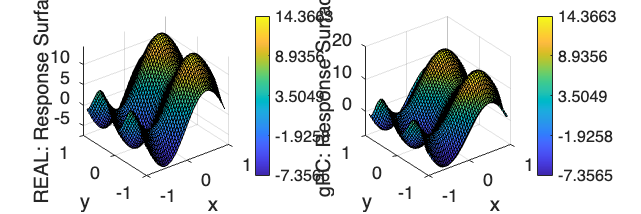

------------------------------------------

gPC Percent Error (on 2D subspace):
   --> AVG:    78.062
   --> MEDIAN: 6.318
   --> MIN:    0.006
   --> MAX:    59746.870
   --> STDEV:  1694.376



[param_combo_full, param_combo] = USER_RUN_gPC_Expansion();

This generates two parameter sets: the full set ( `param_combo_full`) and a subset (`param_combo`) of the full set. Here, we'll use the full set. 

full_vec_aoa = ((param_combo_full(:,2) + 1)/2).*aoa_high;
full_vec_camber = (((param_combo_full(:,3) + 1)/2).*(camber_high - camber_low)) + camber_low;

The Reynolds number range has two options: log transformed and non-log transformed. Here, we will do both. 

full_vec_nologRe = (((param_combo_full(:,1) + 1)/2)).*(Re_high - Re_low) + Re_low;
full_vec_Re_temp = (((param_combo_full(:,1) + 1)/2)).*(log10(Re_high)  - log10(Re_low)) + log10(Re_low);
full_vec_logRe = 10.^full_vec_Re_temp;

Now form the final parameter sets: 

params_nolog = table(full_vec_nologRe, full_vec_aoa, full_vec_camber);
params_log = table(full_vec_logRe, full_vec_aoa, full_vec_camber);

Save the `params` tables as csv files: 

writetable(params_nolog, "../data/parameters/gPC_Params_nologRe.csv", ...
    'WriteVariableNames',false)
writetable(params_log, "../data/parameters/gPC_Params_logRe.csv", ...
    'WriteVariableNames',false)

### Neural Network (NN)

Add the proper folder to the MATLAB environment before getting started: 

addpath('../src/matlab/nn')

Run the following function to build and train the NN model: 

go_Go_ANN()